# Impulse Response in VR

close all; clear; clc;
list_factory = fieldnames(get(groot,'factory'));
index_interpreter = find(contains(list_factory,'Interpreter'));
for i = 1:length(index_interpreter)
    default_name = strrep(list_factory{index_interpreter(i)},'factory','default');
    set(groot, default_name,'latex');
end
clear list_factory index_interpreter default_name i;

% Add paths
addpath(genpath('Data'));
addpath(genpath('RL_Responses'));

% Settings
SETTINGS.titleFS    = 18;
SETTINGS.subtitleFS = 15;
SETTINGS.labelFS    = 12;
fs = 44100;

## Excitation Signal (Impulse)

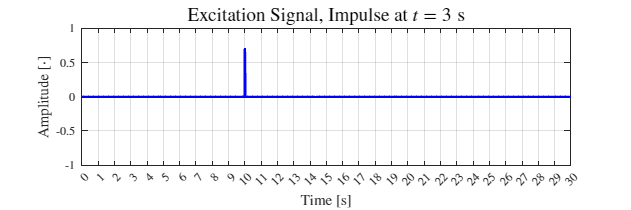

duration_s = 30;
ExcitationSignal = zeros(duration_s*fs, 1);

impulse_amp         = 0.7;
impulse_happening_s = 10;

ExcitationSignal(impulse_happening_s*fs) = impulse_amp;
% audiowrite('Data\Impulse.wav', ExcitationSignal, fs);

f = figure('Position', [10 10 900 300]);
t     = (0:1/fs:(length(ExcitationSignal)-1)/fs)';
p = plot(t, ExcitationSignal);
p.Color = [0 0 1];
p.LineWidth = 2;
grid on;
xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);
title('Excitation Signal, Impulse at $t=3\; \mathrm{s}$', 'FontSize', SETTINGS.subtitleFS);
xticks(0:1:duration_s);
ylim([-1 1]);

% exportgraphics(f, 'Figures\ExcitationSignal_Impulse.pdf', 'Resolution', 200);

## Read Data

%-------------- TEST 1 -------------------------%
test1.dataRaw = readmatrix('Test1.txt');
test1.dataL = test1.dataRaw(1:2:end);
test1.dataR = test1.dataRaw(2:2:end);
test1.t     = (0:1/fs:(length(test1.dataL)-1)/fs)';

test1.signalL = [test1.t test1.dataL];
test1.signalR = [test1.t test1.dataR];
[test1.maxL, test1.IL] = max(test1.dataL);
[test1.maxR, test1.IR] = max(test1.dataR);
for i = 1:length(test1.dataL)
    if (test1.dataL(i) > 0.001)
        test1.shiftL = i;
        break
    end
end
for i = 1:length(test1.dataR)
    if (test1.dataR(i) > 0.001)
        test1.shiftR = i;
        break
    end
end
test1.signalL(any(abs(test1.signalL) < test1.maxL/1000,2),:) = [];
test1.signalR(any(abs(test1.signalR) < test1.maxR/1000,2),:) = [];

%-------------- TEST 2 -------------------------%
test2.dataRaw = readmatrix('Test2.txt');
test2.dataL = test2.dataRaw(1:2:end);
test2.dataR = test2.dataRaw(2:2:end);
test2.t     = (0:1/fs:(length(test2.dataL)-1)/fs)';

test2.signalL = [test2.t test2.dataL];
test2.signalR = [test2.t test2.dataR];
[test2.maxL, test2.IL] = max(test2.dataL);
[test2.maxR, test2.IR] = max(test2.dataR);
for i = 1:length(test2.dataL)
    if (test2.dataL(i) > 0.001)
        test2.shiftL = i;
        break
    end
end
for i = 1:length(test2.dataR)
    if (test2.dataR(i) > 0.001)
        test2.shiftR = i;
        break
    end
end
test2.signalL(any(abs(test2.signalL) < test2.maxL/1000,2),:) = [];
test2.signalR(any(abs(test2.signalR) < test2.maxR/1000,2),:) = [];

%-------------- TEST 3 -------------------------%
test3.dataRaw = readmatrix('Test3.txt');
test3.dataL = test3.dataRaw(1:2:end);
test3.dataR = test3.dataRaw(2:2:end);
test3.t     = (0:1/fs:(length(test3.dataL)-1)/fs)';

test3.signalL = [test3.t test3.dataL];
test3.signalR = [test3.t test3.dataR];
[test3.maxL, test3.IL] = max(test3.dataL);
[test3.maxR, test3.IR] = max(test3.dataR);
for i = 1:length(test3.dataL)
    if (test3.dataL(i) > 0.005)
        test3.shiftL = i;
        break
    end
end
for i = 1:length(test3.dataR)
    if (test3.dataR(i) > 0.005)
        test3.shiftR = i;
        break
    end
end
test3.signalL(any(abs(test3.signalL) < test3.maxL/1000,2),:) = [];
test3.signalR(any(abs(test3.signalR) < test3.maxR/1000,2),:) = [];

%-------------- TEST 4 -------------------------%
test4.dataRaw = readmatrix('Test4.txt');
test4.dataL = test4.dataRaw(1:2:end);
test4.dataR = test4.dataRaw(2:2:end);
test4.t     = (0:1/fs:(length(test4.dataL)-1)/fs)';

test4.signalL = [test4.t test4.dataL];
test4.signalR = [test4.t test4.dataR];
[test4.maxL, test4.IL] = max(test4.dataL);
[test4.maxR, test4.IR] = max(test4.dataR);
for i = 1:length(test4.dataL)
    if (test4.dataL(i) > 0.005)
        test4.shiftL = i;
        break
    end
end
for i = 1:length(test4.dataR)
    if (test4.dataR(i) > 0.005)
        test4.shiftR = i;
        break
    end
end
test4.signalL(any(abs(test4.signalL) < test4.maxL/1000,2),:) = [];
test4.signalR(any(abs(test4.signalR) < test4.maxR/1000,2),:) = [];

%-------------- TEST 5 -------------------------%
test5.dataRaw = readmatrix('Test5.txt');
test5.dataL = test5.dataRaw(1:2:end);
test5.dataR = test5.dataRaw(2:2:end);
test5.t     = (0:1/fs:(length(test5.dataL)-1)/fs)';

test5.signalL = [test5.t test5.dataL];
test5.signalR = [test5.t test5.dataR];
[test5.maxL, test5.IL] = max(test5.dataL);
[test5.maxR, test5.IR] = max(test5.dataR);
for i = 1:length(test5.dataL)
    if (test5.dataL(i) > 0.005)
        test5.shiftL = i;
        break
    end
end
for i = 1:length(test5.dataR)
    if (test5.dataR(i) > 0.005)
        test5.shiftR = i;
        break
    end
end
test5.signalL(any(abs(test5.signalL) < test5.maxL/1000,2),:) = [];
test5.signalR(any(abs(test5.signalR) < test5.maxR/1000,2),:) = [];

## Raw Plots

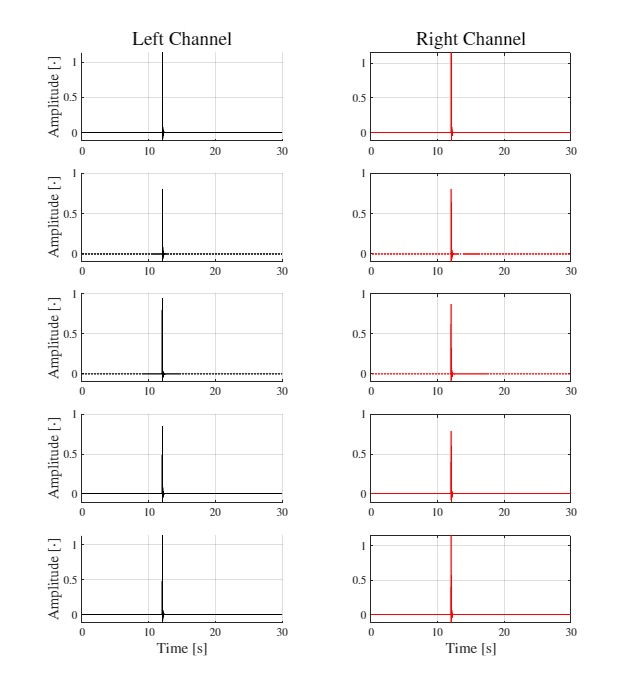

f = figure('Position', [10 10 900 1000]);
tiledlayout(5, 2);

nexttile;
hold on
    p = plot(test1.t, test1.dataL);
    p.Color = [0 0 0];
hold off
grid on
% xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);
title('Left Channel', 'FontSize', SETTINGS.subtitleFS)

nexttile;
p = plot(test1.t, test1.dataR);
p.Color = [1 0 0];
grid on
title('Right Channel', 'FontSize', SETTINGS.subtitleFS)

nexttile;
hold on
    p = plot(test2.t, test2.dataL);
    p.Color = [0 0 0];
    
hold off
grid on
% xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);

nexttile;
p = plot(test2.t, test2.dataR);
    p.Color = [1 0 0];
grid on

nexttile;
hold on
    p = plot(test3.t, test3.dataL);
    p.Color = [0 0 0];
hold off
grid on
% xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);

nexttile;
    p = plot(test3.t, test3.dataR);
    p.Color = [1 0 0];
grid on

nexttile;
hold on
    p = plot(test4.t, test4.dataL);
    p.Color = [0 0 0];
hold off
grid on
% xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);

nexttile;
p = plot(test4.t, test4.dataR);
p.Color = [1 0 0];
grid on

nexttile;
hold on
    p = plot(test5.t, test5.dataL);
    p.Color = [0 0 0];
hold off
grid on
xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);

nexttile;
p = plot(test5.t, test5.dataR);
p.Color = [1 0 0];
grid on
xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);


% exportgraphics(f, 'Figures\RawPlots.pdf', 'Resolution', 200);

## Real Life Measurement

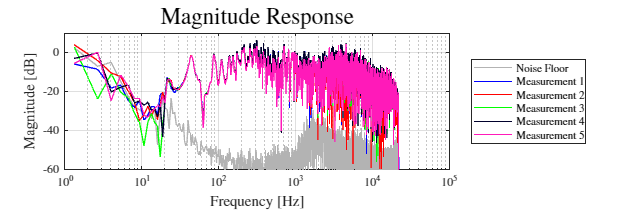

load('NoiseFloor.mat');
MR_floor = measurementData.MagnitudeResponse;
load('ImpulseResponses.mat');
load('MagnitudeResponses.mat');
load('PhaseResponses.mat');
colors          = zeros(6, 3);
colors(6, :)    = [1 1 1] * 0.7; % grey for noise floor
colors(1:5, :)  = distinguishable_colors(5, 'w');

f = figure('Position', [10 10 900 300]);
s = semilogx(MR_floor.Frequency, MR_floor.MagnitudeDB);
s.Color = [1 1 1].*0.7;
hold on
    s = semilogx(MR(1).Frequency, MR(1).MagnitudeDB);
    s.Color = colors(1, :);
    s = semilogx(MR(2).Frequency, MR(2).MagnitudeDB);
    s.Color = colors(2, :);
    s = semilogx(MR(3).Frequency, MR(3).MagnitudeDB);
    s.Color = colors(3, :);
    s = semilogx(MR(4).Frequency, MR(4).MagnitudeDB);
    s.Color = colors(4, :);
    s = semilogx(MR(5).Frequency, MR(5).MagnitudeDB);
    s.Color = colors(5, :);
hold off
grid on;
ylim([-60 10]);
% xlim([0.05 0.07])
title('Magnitude Response', 'FontSize', SETTINGS.titleFS);
ylabel('Magnitude $[\mathrm{dB}]$', 'FontSize', SETTINGS.labelFS);
xlabel('Frequency $[\mathrm{Hz}]$', 'FontSize', SETTINGS.labelFS);
legend('Noise Floor', 'Measurement 1', 'Measurement 2', 'Measurement 3', 'Measurement 4', 'Measurement 5','Location', 'eastoutside')

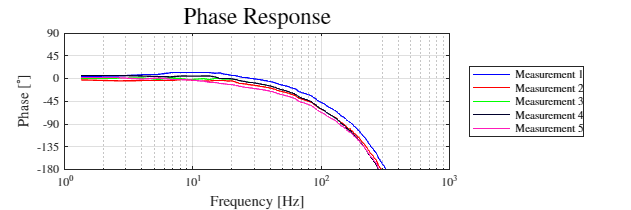

% exportgraphics(f, 'Figures/MagnitudeResponse_All_withFloor.pdf', 'Resolution', 300);

f = figure('Position', [10 10 900 300]);
s = semilogx(PR(1).Frequency, PR(1).Phase);
s.Color = colors(1, :);
hold on
for i = 2:5
    s = semilogx(PR(i).Frequency, PR(i).Phase);
    s.Color = colors(i, :);
end
hold off
grid on;
ylim([-180 90])
yticks(-180:45:90)
% xlim([0.05 0.07])
title('Phase Response', 'FontSize', SETTINGS.titleFS);
ylabel('Phase $[\mathrm{^\circ}]$', 'FontSize', SETTINGS.labelFS);
xlabel('Frequency $[\mathrm{Hz}]$', 'FontSize', SETTINGS.labelFS);
legend('Measurement 1', 'Measurement 2', 'Measurement 3', 'Measurement 4', 'Measurement 5', 'Location', 'eastoutside')

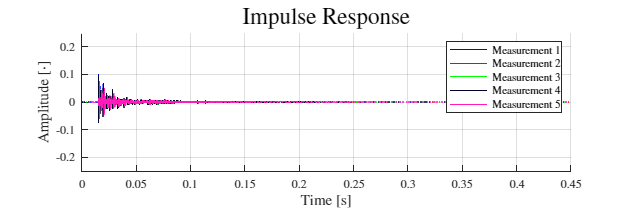

%exportgraphics(f, 'Figures/PhaseResponse_All.pdf', 'Resolution', 300);


% Correcting time delay
I = zeros(5, 1);
for i = 1:5
    % [~, I(i)]    = max(IR(i).Amplitude);
    for j = 1:length(IR(i).Amplitude)
        if (IR(i).Amplitude(j) > 0.01)
            I(i) = j;
            break
        end
    end
end
for i = 1:5
    IR(i).Time      = IR(i).Time - IR(i).Time(I(i)) + (7.79-1.28*2)/343;
end

f = figure('Position', [10 10 900 300]);
hold on
    p = plot(IR(1).Time, IR(1).Amplitude);
    p.Color = colors(1, :);
    p = plot(IR(2).Time, IR(2).Amplitude);
    p.Color = colors(2, :);
    p = plot(IR(3).Time, IR(3).Amplitude);
    p.Color = colors(3, :);
    p = plot(IR(4).Time, IR(4).Amplitude);
    p.Color = colors(4, :);
    p = plot(IR(5).Time, IR(5).Amplitude);
    p.Color = colors(5, :);
hold off
grid on;
xlim([0 0.45])
ylim([-0.25 0.25])
title('Impulse Response', 'FontSize', SETTINGS.titleFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);
xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
legend('Measurement 1', 'Measurement 2', 'Measurement 3', 'Measurement 4', 'Measurement 5', 'Location', 'northeast')

%exportgraphics(f, 'Figures/ImpulseResponse_All.pdf', 'Resolution', 300);

## Timestamps based on distances to mirror sources

distances       = readmatrix('distances.txt');
c_air       = 343;
timestamps  = distances./c_air;

## Comparison

% Align in time
test1.signalL(:, 1)      = test1.signalL(:, 1) - test1.t(test1.shiftL) + (7.79-1.28*2)/343;
test1.signalR(:, 1)      = test1.signalR(:, 1) - test1.t(test1.shiftR) + (7.79-1.28*2)/343;
test2.signalL(:, 1)      = test2.signalL(:, 1) - test2.t(test2.shiftL) + (7.79-1.28*2)/343;
test2.signalR(:, 1)      = test2.signalR(:, 1) - test2.t(test2.shiftR) + (7.79-1.28*2)/343;
test3.signalL(:, 1)      = test3.signalL(:, 1) - test3.t(test3.shiftL) + (7.79-1.28*2)/343;
test3.signalR(:, 1)      = test3.signalR(:, 1) - test3.t(test3.shiftR) + (7.79-1.28*2)/343;
test4.signalL(:, 1)      = test4.signalL(:, 1) - test4.t(test4.shiftL) + (7.79-1.28*2)/343;
test4.signalR(:, 1)      = test4.signalR(:, 1) - test4.t(test4.shiftR) + (7.79-1.28*2)/343;
test5.signalL(:, 1)      = test5.signalL(:, 1) - test5.t(test5.shiftL) + (7.79-1.28*2)/343;
test5.signalR(:, 1)      = test5.signalR(:, 1) - test5.t(test5.shiftR) + (7.79-1.28*2)/343;

% Align in amplitude (normalize)
test1.signalL(:, 2) = test1.signalL(:, 2) ./max(test1.signalL(:, 2));
test1.signalR(:, 2) = test1.signalR(:, 2) ./max(test1.signalR(:, 2)); 
test2.signalL(:, 2) = test2.signalL(:, 2) ./max(test2.signalL(:, 2));
test2.signalR(:, 2) = test2.signalR(:, 2) ./max(test2.signalR(:, 2)); 
test3.signalL(:, 2) = test3.signalL(:, 2) ./max(test3.signalL(:, 2));
test3.signalR(:, 2) = test3.signalR(:, 2) ./max(test3.signalR(:, 2)); 
test4.signalL(:, 2) = test4.signalL(:, 2) ./max(test4.signalL(:, 2));
test4.signalR(:, 2) = test4.signalR(:, 2) ./max(test4.signalR(:, 2)); 
test5.signalL(:, 2) = test5.signalL(:, 2) ./max(test5.signalL(:, 2));
test5.signalR(:, 2) = test5.signalR(:, 2) ./max(test5.signalR(:, 2)); 

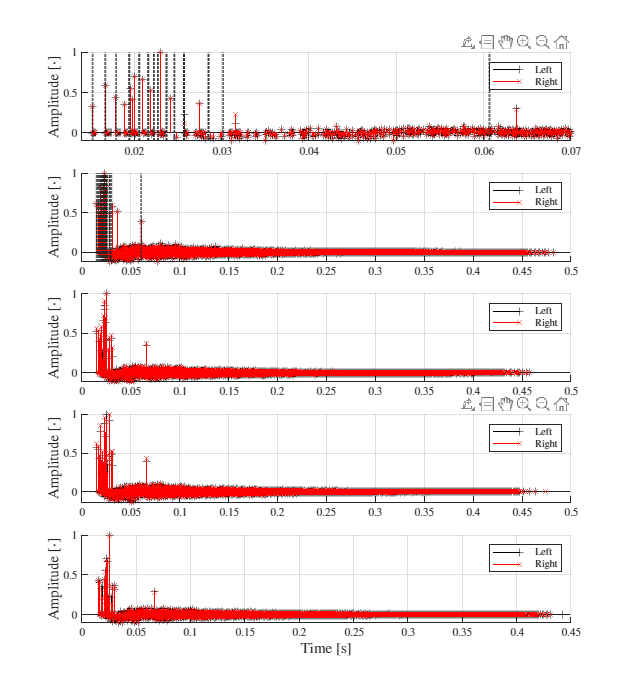

f = figure('Position', [10 10 900 1000]);
tiledlayout(5, 1);

nexttile;
hold on
    s = stem(test1.signalL(:, 1), test1.signalL(:, 2));
    s.Color = [0 0 0];
    s.Marker = "+";
    s = stem(test1.signalR(:, 1), test1.signalR(:, 2));
    s.Color = [1 0 0];
    s.Marker = "x";
for i = 1:size(timestamps, 1)
    xline(timestamps(i), ':', 'LineWidth', 1.5)
end
hold off
grid on
% xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);
legend('Left', 'Right')
xlim([0.014 0.07])

nexttile;
hold on
    s = stem(test2.signalL(:, 1), test2.signalL(:, 2));
    s.Color = [0 0 0];
    s.Marker = "+";
    s = stem(test2.signalR(:, 1), test2.signalR(:, 2));
    s.Color = [1 0 0];
    s.Marker = "x";
for i = 1:size(timestamps, 1)
    xline(timestamps(i), ':', 'LineWidth', 1.5)
end

hold off
grid on
% xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);
legend('Left', 'Right')

nexttile;
hold on
    s = stem(test3.signalL(:, 1), test3.signalL(:, 2));
    s.Color = [0 0 0];
    s.Marker = "+";
    s = stem(test3.signalR(:, 1), test3.signalR(:, 2));
    s.Color = [1 0 0];
    s.Marker = "x";

hold off
grid on
% xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);
legend('Left', 'Right')

nexttile;
hold on
    s = stem(test4.signalL(:, 1), test4.signalL(:, 2));
    s.Color = [0 0 0];
    s.Marker = "+";
    s = stem(test4.signalR(:, 1), test4.signalR(:, 2));
    s.Color = [1 0 0];
    s.Marker = "x";

hold off
grid on
% xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);
legend('Left', 'Right')

nexttile;
hold on
    s = stem(test5.signalL(:, 1), test5.signalL(:, 2));
    s.Color = [0 0 0];
    s.Marker = "+";
    s = stem(test5.signalR(:, 1), test5.signalR(:, 2));
    s.Color = [1 0 0];
    s.Marker = "x";

hold off
grid on
xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);
legend('Left', 'Right')


% exportgraphics(f, 'Figures\IR_Comparison_all.pdf', 'Resolution', 200)

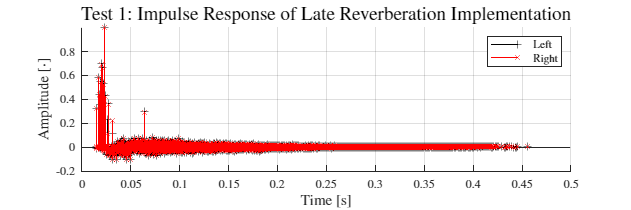

f = figure('Position', [10 10 900 300]);
hold on
    s = stem(test1.signalL(:, 1), test1.signalL(:, 2));
    s.Color = [0 0 0];
    s.Marker = "+";
    s = stem(test1.signalR(:, 1), test1.signalR(:, 2));
    s.Color = [1 0 0];
    s.Marker = "x";
hold off
grid on
xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);
legend('Left', 'Right')
title('Test 1: Impulse Response of Late Reverberation Implementation', 'FontSize', SETTINGS.subtitleFS)

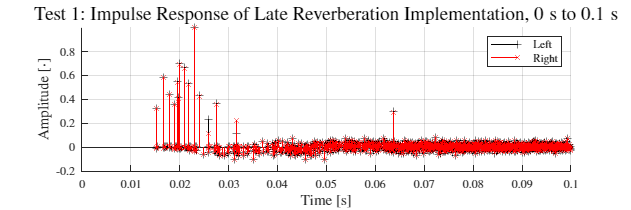

% exportgraphics(f, 'Figures\Test1_IR.pdf', 'Resolution', 200);

f = figure('Position', [10 10 900 300]);
hold on
    s = stem(test1.signalL(:, 1), test1.signalL(:, 2));
    s.Color = [0 0 0];
    s.Marker = "+";
    s = stem(test1.signalR(:, 1), test1.signalR(:, 2));
    s.Color = [1 0 0];
    s.Marker = "x";
hold off
grid on
xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);
legend('Left', 'Right')
xlim([0 0.1])
title('Test 1: Impulse Response of Late Reverberation Implementation, $0\; \mathrm{s}$ to $0.1\; \mathrm{s}$', 'FontSize', SETTINGS.subtitleFS)

% exportgraphics(f, 'Figures\Test1_IR_ZOOM.pdf', 'Resolution', 200);

## Magnitude Responses

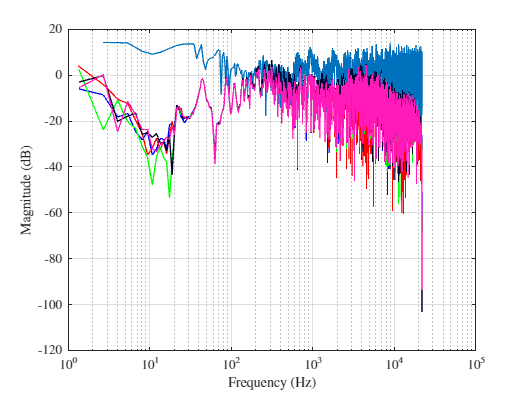

h = test1.dataL;
[mh, ih] = max(h);
h(1:ih-1) = [];
Nfft = 8192;
[H,F] = freqz(h,1,Nfft,fs);

figure();
semilogx(F,mag2db(abs(H))); 
hold on
    s = semilogx(MR(1).Frequency, MR(1).MagnitudeDB);
    s.Color = colors(1, :);
    s = semilogx(MR(2).Frequency, MR(2).MagnitudeDB);
    s.Color = colors(2, :);
    s = semilogx(MR(3).Frequency, MR(3).MagnitudeDB);
    s.Color = colors(3, :);
    s = semilogx(MR(4).Frequency, MR(4).MagnitudeDB);
    s.Color = colors(4, :);
    s = semilogx(MR(5).Frequency, MR(5).MagnitudeDB);
    s.Color = colors(5, :);
hold off

grid on;
xlabel('Frequency (Hz)'); ylabel('Magnitude (dB)');

## Sound Strength

Since the calculation for *sound strength* requires the pressure $10\; \mathrm{m}$ from the source in free field, and the longest dimension is shorter than $8\; \mathrm{m}$ it **does not make sense **to perform the test.

## Reverberance (Early Decay Time)

drop_10dB = 10^(-10/20);
drop_20dB = 10^(-20/20);
drop_30dB = 10^(-30/20);

%-------- Real Life Measurements ----------------%
RL_EDT = zeros(5, 3);

% Measurement 1
RL_meas1_10dB = [IR(1).Time IR(1).Amplitude]; 
RL_meas1_20dB = [IR(1).Time IR(1).Amplitude]; 
RL_meas1_30dB = [IR(1).Time IR(1).Amplitude]; 
RL_meas1_10dB(any(abs(RL_meas1_10dB(:, 2)) < max(RL_meas1_10dB(:, 2))*drop_10dB,2),:) = [];
RL_meas1_20dB(any(abs(RL_meas1_20dB(:, 2)) < max(RL_meas1_20dB(:, 2))*drop_20dB,2),:) = [];
RL_meas1_30dB(any(abs(RL_meas1_30dB(:, 2)) < max(RL_meas1_30dB(:, 2))*drop_30dB,2),:) = [];
RL_EDT(1, :) = [RL_meas1_10dB(end, 1) RL_meas1_20dB(end, 1) RL_meas1_30dB(end, 1)];

% Measurement 2
RL_meas2_10dB = [IR(2).Time IR(2).Amplitude]; 
RL_meas2_20dB = [IR(2).Time IR(2).Amplitude]; 
RL_meas2_30dB = [IR(2).Time IR(2).Amplitude]; 
RL_meas2_10dB(any(abs(RL_meas2_10dB(:, 2)) < max(RL_meas2_10dB(:, 2))*drop_10dB,2),:) = [];
RL_meas2_20dB(any(abs(RL_meas2_20dB(:, 2)) < max(RL_meas2_20dB(:, 2))*drop_20dB,2),:) = [];
RL_meas2_30dB(any(abs(RL_meas2_30dB(:, 2)) < max(RL_meas2_30dB(:, 2))*drop_30dB,2),:) = [];
RL_EDT(2, :) = [RL_meas2_10dB(end, 1) RL_meas2_20dB(end, 1) RL_meas2_30dB(end, 1)];

% Measurement 3
RL_meas3_10dB = [IR(3).Time IR(3).Amplitude]; 
RL_meas3_20dB = [IR(3).Time IR(3).Amplitude]; 
RL_meas3_30dB = [IR(3).Time IR(3).Amplitude]; 
RL_meas3_10dB(any(abs(RL_meas3_10dB(:, 2)) < max(RL_meas3_10dB(:, 2))*drop_10dB,2),:) = [];
RL_meas3_20dB(any(abs(RL_meas3_20dB(:, 2)) < max(RL_meas3_20dB(:, 2))*drop_20dB,2),:) = [];
RL_meas3_30dB(any(abs(RL_meas3_30dB(:, 2)) < max(RL_meas3_30dB(:, 2))*drop_30dB,2),:) = [];
RL_EDT(3, :) = [RL_meas3_10dB(end, 1) RL_meas3_20dB(end, 1) RL_meas3_30dB(end, 1)];

% Measurement 4
RL_meas4_10dB = [IR(4).Time IR(4).Amplitude]; 
RL_meas4_20dB = [IR(4).Time IR(4).Amplitude]; 
RL_meas4_30dB = [IR(4).Time IR(4).Amplitude]; 
RL_meas4_10dB(any(abs(RL_meas4_10dB(:, 2)) < max(RL_meas4_10dB(:, 2))*drop_10dB,2),:) = [];
RL_meas4_20dB(any(abs(RL_meas4_20dB(:, 2)) < max(RL_meas4_20dB(:, 2))*drop_20dB,2),:) = [];
RL_meas4_30dB(any(abs(RL_meas4_30dB(:, 2)) < max(RL_meas4_30dB(:, 2))*drop_30dB,2),:) = [];
RL_EDT(4, :) = [RL_meas4_10dB(end, 1) RL_meas4_20dB(end, 1) RL_meas4_30dB(end, 1)];

% Measurement 5
RL_meas5_10dB = [IR(5).Time IR(5).Amplitude]; 
RL_meas5_20dB = [IR(5).Time IR(5).Amplitude]; 
RL_meas5_30dB = [IR(5).Time IR(5).Amplitude]; 
RL_meas5_10dB(any(abs(RL_meas5_10dB(:, 2)) < max(RL_meas5_10dB(:, 2))*drop_10dB,2),:) = [];
RL_meas5_20dB(any(abs(RL_meas5_20dB(:, 2)) < max(RL_meas5_20dB(:, 2))*drop_20dB,2),:) = [];
RL_meas5_30dB(any(abs(RL_meas5_30dB(:, 2)) < max(RL_meas5_30dB(:, 2))*drop_30dB,2),:) = [];
RL_EDT(5, :) = [RL_meas5_10dB(end, 1) RL_meas5_20dB(end, 1) RL_meas5_30dB(end, 1)];

%-------- Virtual Reality Measurements ----------------%
VR_L_EDT = zeros(5, 3);
VR_R_EDT = zeros(5, 3);

% Measurement 1
VR_L_meas1_10dB       = [test1.t test1.dataL]; 
VR_L_meas1_10dB(:, 1) = VR_L_meas1_10dB(:, 1) - test1.t(test1.shiftL) + (7.79-1.28*2)/343;
VR_L_meas1_20dB = VR_L_meas1_10dB; 
VR_L_meas1_30dB = VR_L_meas1_10dB; 
VR_L_meas1_10dB(any(abs(VR_L_meas1_10dB(:, 2)) < max(VR_L_meas1_10dB(:, 2))*drop_10dB,2),:) = [];
VR_L_meas1_20dB(any(abs(VR_L_meas1_20dB(:, 2)) < max(VR_L_meas1_20dB(:, 2))*drop_20dB,2),:) = [];
VR_L_meas1_30dB(any(abs(VR_L_meas1_30dB(:, 2)) < max(VR_L_meas1_30dB(:, 2))*drop_30dB,2),:) = [];
VR_L_EDT(1, :) = [VR_L_meas1_10dB(end, 1) VR_L_meas1_20dB(end, 1) VR_L_meas1_30dB(end, 1)];

VR_R_meas1_10dB       = [test1.t test1.dataR]; 
VR_R_meas1_10dB(:, 1) = VR_R_meas1_10dB(:, 1) - test1.t(test1.shiftR) + (7.79-1.28*2)/343;
VR_R_meas1_20dB = VR_R_meas1_10dB; 
VR_R_meas1_30dB = VR_R_meas1_10dB; 
VR_R_meas1_10dB(any(abs(VR_R_meas1_10dB(:, 2)) < max(VR_R_meas1_10dB(:, 2))*drop_10dB,2),:) = [];
VR_R_meas1_20dB(any(abs(VR_R_meas1_20dB(:, 2)) < max(VR_R_meas1_20dB(:, 2))*drop_20dB,2),:) = [];
VR_R_meas1_30dB(any(abs(VR_R_meas1_30dB(:, 2)) < max(VR_R_meas1_30dB(:, 2))*drop_30dB,2),:) = [];
VR_R_EDT(1, :) = [VR_R_meas1_10dB(end, 1) VR_R_meas1_20dB(end, 1) VR_R_meas1_30dB(end, 1)];

% Measurement 2
VR_L_meas2_10dB       = [test2.t test2.dataL]; 
VR_L_meas2_10dB(:, 1) = VR_L_meas2_10dB(:, 1) - test2.t(test2.shiftL) + (7.79-1.28*2)/343;
VR_L_meas2_20dB = VR_L_meas2_10dB; 
VR_L_meas2_30dB = VR_L_meas2_10dB; 
VR_L_meas2_10dB(any(abs(VR_L_meas2_10dB(:, 2)) < max(VR_L_meas2_10dB(:, 2))*drop_10dB,2),:) = [];
VR_L_meas2_20dB(any(abs(VR_L_meas2_20dB(:, 2)) < max(VR_L_meas2_20dB(:, 2))*drop_20dB,2),:) = [];
VR_L_meas2_30dB(any(abs(VR_L_meas2_30dB(:, 2)) < max(VR_L_meas2_30dB(:, 2))*drop_30dB,2),:) = [];
VR_L_EDT(2, :) = [VR_L_meas2_10dB(end, 1) VR_L_meas2_20dB(end, 1) VR_L_meas2_30dB(end, 1)];

VR_R_meas2_10dB       = [test2.t test2.dataR]; 
VR_R_meas2_10dB(:, 1) = VR_R_meas2_10dB(:, 1) - test2.t(test2.shiftR) + (7.79-1.28*2)/343;
VR_R_meas2_20dB = VR_R_meas2_10dB; 
VR_R_meas2_30dB = VR_R_meas2_10dB; 
VR_R_meas2_10dB(any(abs(VR_R_meas2_10dB(:, 2)) < max(VR_R_meas2_10dB(:, 2))*drop_10dB,2),:) = [];
VR_R_meas2_20dB(any(abs(VR_R_meas2_20dB(:, 2)) < max(VR_R_meas2_20dB(:, 2))*drop_20dB,2),:) = [];
VR_R_meas2_30dB(any(abs(VR_R_meas2_30dB(:, 2)) < max(VR_R_meas2_30dB(:, 2))*drop_30dB,2),:) = [];
VR_R_EDT(2, :) = [VR_R_meas2_10dB(end, 1) VR_R_meas2_20dB(end, 1) VR_R_meas2_30dB(end, 1)];

% Measurement 3
VR_L_meas3_10dB       = [test3.t test3.dataL]; 
VR_L_meas3_10dB(:, 1) = VR_L_meas3_10dB(:, 1) - test3.t(test3.shiftL) + (7.79-1.28*2)/343;
VR_L_meas3_20dB = VR_L_meas3_10dB; 
VR_L_meas3_30dB = VR_L_meas3_10dB; 
VR_L_meas3_10dB(any(abs(VR_L_meas3_10dB(:, 2)) < max(VR_L_meas3_10dB(:, 2))*drop_10dB,2),:) = [];
VR_L_meas3_20dB(any(abs(VR_L_meas3_20dB(:, 2)) < max(VR_L_meas3_20dB(:, 2))*drop_20dB,2),:) = [];
VR_L_meas3_30dB(any(abs(VR_L_meas3_30dB(:, 2)) < max(VR_L_meas3_30dB(:, 2))*drop_30dB,2),:) = [];
VR_L_EDT(3, :) = [VR_L_meas3_10dB(end, 1) VR_L_meas3_20dB(end, 1) VR_L_meas3_30dB(end, 1)];

VR_R_meas3_10dB       = [test3.t test3.dataR]; 
VR_R_meas3_10dB(:, 1) = VR_R_meas3_10dB(:, 1) - test3.t(test3.shiftR) + (7.79-1.28*2)/343;
VR_R_meas3_20dB = VR_R_meas3_10dB; 
VR_R_meas3_30dB = VR_R_meas3_10dB; 
VR_R_meas3_10dB(any(abs(VR_R_meas3_10dB(:, 2)) < max(VR_R_meas3_10dB(:, 2))*drop_10dB,2),:) = [];
VR_R_meas3_20dB(any(abs(VR_R_meas3_20dB(:, 2)) < max(VR_R_meas3_20dB(:, 2))*drop_20dB,2),:) = [];
VR_R_meas3_30dB(any(abs(VR_R_meas3_30dB(:, 2)) < max(VR_R_meas3_30dB(:, 2))*drop_30dB,2),:) = [];
VR_R_EDT(3, :) = [VR_R_meas3_10dB(end, 1) VR_R_meas3_20dB(end, 1) VR_R_meas3_30dB(end, 1)];

% Measurement 4
VR_L_meas4_10dB       = [test4.t test4.dataL]; 
VR_L_meas4_10dB(:, 1) = VR_L_meas4_10dB(:, 1) - test4.t(test4.shiftL) + (7.79-1.28*2)/343;
VR_L_meas4_20dB = VR_L_meas4_10dB; 
VR_L_meas4_30dB = VR_L_meas4_10dB; 
VR_L_meas4_10dB(any(abs(VR_L_meas4_10dB(:, 2)) < max(VR_L_meas4_10dB(:, 2))*drop_10dB,2),:) = [];
VR_L_meas4_20dB(any(abs(VR_L_meas4_20dB(:, 2)) < max(VR_L_meas4_20dB(:, 2))*drop_20dB,2),:) = [];
VR_L_meas4_30dB(any(abs(VR_L_meas4_30dB(:, 2)) < max(VR_L_meas4_30dB(:, 2))*drop_30dB,2),:) = [];
VR_L_EDT(4, :) = [VR_L_meas4_10dB(end, 1) VR_L_meas4_20dB(end, 1) VR_L_meas4_30dB(end, 1)];

VR_R_meas4_10dB       = [test4.t test4.dataR]; 
VR_R_meas4_10dB(:, 1) = VR_R_meas4_10dB(:, 1) - test4.t(test4.shiftR) + (7.79-1.28*2)/343;
VR_R_meas4_20dB = VR_R_meas4_10dB; 
VR_R_meas4_30dB = VR_R_meas4_10dB; 
VR_R_meas4_10dB(any(abs(VR_R_meas4_10dB(:, 2)) < max(VR_R_meas4_10dB(:, 2))*drop_10dB,2),:) = [];
VR_R_meas4_20dB(any(abs(VR_R_meas4_20dB(:, 2)) < max(VR_R_meas4_20dB(:, 2))*drop_20dB,2),:) = [];
VR_R_meas4_30dB(any(abs(VR_R_meas4_30dB(:, 2)) < max(VR_R_meas4_30dB(:, 2))*drop_30dB,2),:) = [];
VR_R_EDT(4, :) = [VR_R_meas4_10dB(end, 1) VR_R_meas4_20dB(end, 1) VR_R_meas4_30dB(end, 1)];

% Measurement 5
VR_L_meas5_10dB       = [test5.t test5.dataL]; 
VR_L_meas5_10dB(:, 1) = VR_L_meas5_10dB(:, 1) - test5.t(test5.shiftL) + (7.79-1.28*2)/343;
VR_L_meas5_20dB = VR_L_meas5_10dB; 
VR_L_meas5_30dB = VR_L_meas5_10dB; 
VR_L_meas5_10dB(any(abs(VR_L_meas5_10dB(:, 2)) < max(VR_L_meas5_10dB(:, 2))*drop_10dB,2),:) = [];
VR_L_meas5_20dB(any(abs(VR_L_meas5_20dB(:, 2)) < max(VR_L_meas5_20dB(:, 2))*drop_20dB,2),:) = [];
VR_L_meas5_30dB(any(abs(VR_L_meas5_30dB(:, 2)) < max(VR_L_meas5_30dB(:, 2))*drop_30dB,2),:) = [];
VR_L_EDT(5, :) = [VR_L_meas5_10dB(end, 1) VR_L_meas5_20dB(end, 1) VR_L_meas5_30dB(end, 1)];

VR_R_meas5_10dB       = [test5.t test5.dataR]; 
VR_R_meas5_10dB(:, 1) = VR_R_meas5_10dB(:, 1) - test5.t(test5.shiftR) + (7.79-1.28*2)/343;
VR_R_meas5_20dB = VR_R_meas5_10dB; 
VR_R_meas5_30dB = VR_R_meas5_10dB; 
VR_R_meas5_10dB(any(abs(VR_R_meas5_10dB(:, 2)) < max(VR_R_meas5_10dB(:, 2))*drop_10dB,2),:) = [];
VR_R_meas5_20dB(any(abs(VR_R_meas5_20dB(:, 2)) < max(VR_R_meas5_20dB(:, 2))*drop_20dB,2),:) = [];
VR_R_meas5_30dB(any(abs(VR_R_meas5_30dB(:, 2)) < max(VR_R_meas5_30dB(:, 2))*drop_30dB,2),:) = [];
VR_R_EDT(5, :) = [VR_R_meas5_10dB(end, 1) VR_R_meas5_20dB(end, 1) VR_R_meas5_30dB(end, 1)];
%------------------------------------------------%

disp(RL_EDT)

    0.0284    0.0428    0.1198
    0.0390    0.1064    0.1739
    0.0293    0.0685    0.1325
    0.0285    0.0623    0.1320
    0.0296    0.0696    0.1331



disp(VR_L_EDT)

    0.0275    0.0638    0.1819
    0.0607    0.0809    0.1877
    0.0665    0.0665    0.1846
    0.0665    0.0665    0.1877
    0.0304    0.0665    0.1591



disp(VR_R_EDT)

    0.0275    0.0638    0.1819
    0.0607    0.0809    0.1877
    0.0665    0.0665    0.1846
    0.0665    0.0809    0.1877
    0.0304    0.0665    0.1591



## Definition, Clarity, and Centre Time

upper_limit = round(0.05*fs); % sample equivalent of 50 ms
inf_limit   = round(4*fs);   % sample equivalent of 10 s (infinity)
te_50 = round(0.05*fs);         % For Cte
te_80 = round(0.08*fs);         % For Cte

%-------- Virtual Reality Measurements ----------------%
VR_L_DCCT = zeros(5, 4); % D50, Cte_50, Cte_80, Ts
VR_R_DCCT = zeros(5, 4); % D50, Cte_50, Cte_80, Ts

% Measurement 1
VR_L_meas1_DCCT       = [test1.t test1.dataL]; 
VR_L_meas1_DCCT(:, 1) = VR_L_meas1_DCCT(:, 1) - test1.t(test1.shiftL) + (7.79-1.28*2)/343;
VR_L_meas1_DCCT(any(VR_L_meas1_DCCT(:, 1) < 0, 2), :) = [];
timesteps_meas1 = (ones(1, size(VR_L_meas1_DCCT, 1)).*(1/fs))';

VR_L_DCCT(1, 1) = (VR_L_meas1_DCCT(1:upper_limit, 2)'.^2 * timesteps_meas1(1:upper_limit)) / (VR_L_meas1_DCCT(1:inf_limit, 2)'.^2 * timesteps_meas1(1:inf_limit)); % Definition
VR_L_DCCT(1, 2) = 10*log10((VR_L_meas1_DCCT(1:te_50, 2)'.^2 * timesteps_meas1(1:te_50)) / (VR_L_meas1_DCCT(te_50:inf_limit, 2)'.^2 * timesteps_meas1(te_50:inf_limit))); % Clarity
VR_L_DCCT(1, 3) = 10*log10((VR_L_meas1_DCCT(1:te_80, 2)'.^2 * timesteps_meas1(1:te_80)) / (VR_L_meas1_DCCT(te_80:inf_limit, 2)'.^2 * timesteps_meas1(te_80:inf_limit)));
VR_L_DCCT(1, 4) = (( VR_L_meas1_DCCT(1:inf_limit, 2).^2 .* ( VR_L_meas1_DCCT(1:inf_limit, 1) ) )' * timesteps_meas1(1:inf_limit)) / (VR_L_meas1_DCCT(1:inf_limit, 2)'.^2 * timesteps_meas1(1:inf_limit)); % centre time

VR_R_meas1_DCCT       = [test1.t test1.dataR]; 
VR_R_meas1_DCCT(:, 1) = VR_R_meas1_DCCT(:, 1) - test1.t(test1.shiftR) + (7.79-1.28*2)/343;
VR_R_meas1_DCCT(any(VR_R_meas1_DCCT(:, 1) < 0, 2), :) = [];
timesteps_meas1 = (ones(1, size(VR_R_meas1_DCCT, 1)).*(1/fs))';

VR_R_DCCT(1, 1) = (VR_R_meas1_DCCT(1:upper_limit, 2)'.^2 * timesteps_meas1(1:upper_limit)) / (VR_R_meas1_DCCT(1:inf_limit, 2)'.^2 * timesteps_meas1(1:inf_limit)); % Definition
VR_R_DCCT(1, 2) = 10*log10((VR_R_meas1_DCCT(1:te_50, 2)'.^2 * timesteps_meas1(1:te_50)) / (VR_R_meas1_DCCT(te_50:inf_limit, 2)'.^2 * timesteps_meas1(te_50:inf_limit))); % Clarity
VR_R_DCCT(1, 3) = 10*log10((VR_R_meas1_DCCT(1:te_80, 2)'.^2 * timesteps_meas1(1:te_80)) / (VR_R_meas1_DCCT(te_80:inf_limit, 2)'.^2 * timesteps_meas1(te_80:inf_limit)));
VR_R_DCCT(1, 4) = (( VR_R_meas1_DCCT(1:inf_limit, 2).^2 .* ( VR_R_meas1_DCCT(1:inf_limit, 1) ) )' * timesteps_meas1(1:inf_limit)) / (VR_R_meas1_DCCT(1:inf_limit, 2)'.^2 * timesteps_meas1(1:inf_limit)); % centre time

% Measurement 2
VR_L_meas2_DCCT       = [test2.t test2.dataL]; 
VR_L_meas2_DCCT(:, 1) = VR_L_meas2_DCCT(:, 1) - test2.t(test2.shiftL) + (7.79-1.28*2)/343;
VR_L_meas2_DCCT(any(VR_L_meas2_DCCT(:, 1) < 0, 2), :) = [];
timesteps_meas2 = (ones(1, size(VR_L_meas2_DCCT, 1)).*(1/fs))';

VR_L_DCCT(2, 1) = (VR_L_meas2_DCCT(1:upper_limit, 2)'.^2 * timesteps_meas2(1:upper_limit)) / (VR_L_meas2_DCCT(1:inf_limit, 2)'.^2 * timesteps_meas2(1:inf_limit)); % Definition
VR_L_DCCT(2, 2) = 10*log10((VR_L_meas2_DCCT(1:te_50, 2)'.^2 * timesteps_meas2(1:te_50)) / (VR_L_meas2_DCCT(te_50:inf_limit, 2)'.^2 * timesteps_meas2(te_50:inf_limit))); % Clarity
VR_L_DCCT(2, 3) = 10*log10((VR_L_meas2_DCCT(1:te_80, 2)'.^2 * timesteps_meas2(1:te_80)) / (VR_L_meas2_DCCT(te_80:inf_limit, 2)'.^2 * timesteps_meas2(te_80:inf_limit)));
VR_L_DCCT(2, 4) = (( VR_L_meas2_DCCT(1:inf_limit, 2).^2 .* ( VR_L_meas2_DCCT(1:inf_limit, 1) ) )' * timesteps_meas2(1:inf_limit)) / (VR_L_meas2_DCCT(1:inf_limit, 2)'.^2 * timesteps_meas2(1:inf_limit)); % centre time

VR_R_meas2_DCCT       = [test2.t test2.dataR]; 
VR_R_meas2_DCCT(:, 1) = VR_R_meas2_DCCT(:, 1) - test2.t(test2.shiftR) + (7.79-1.28*2)/343;
VR_R_meas2_DCCT(any(VR_R_meas2_DCCT(:, 1) < 0, 2), :) = [];
timesteps_meas2 = (ones(1, size(VR_R_meas2_DCCT, 1)).*(1/fs))';

VR_R_DCCT(2, 1) = (VR_R_meas2_DCCT(1:upper_limit, 2)'.^2 * timesteps_meas2(1:upper_limit)) / (VR_R_meas2_DCCT(1:inf_limit, 2)'.^2 * timesteps_meas2(1:inf_limit)); % Definition
VR_R_DCCT(2, 2) = 10*log10((VR_R_meas2_DCCT(1:te_50, 2)'.^2 * timesteps_meas2(1:te_50)) / (VR_R_meas2_DCCT(te_50:inf_limit, 2)'.^2 * timesteps_meas2(te_50:inf_limit))); % Clarity
VR_R_DCCT(2, 3) = 10*log10((VR_R_meas2_DCCT(1:te_80, 2)'.^2 * timesteps_meas2(1:te_80)) / (VR_R_meas2_DCCT(te_80:inf_limit, 2)'.^2 * timesteps_meas2(te_80:inf_limit)));
VR_R_DCCT(2, 4) = (( VR_R_meas2_DCCT(1:inf_limit, 2).^2 .* ( VR_R_meas2_DCCT(1:inf_limit, 1) ) )' * timesteps_meas2(1:inf_limit)) / (VR_R_meas2_DCCT(1:inf_limit, 2)'.^2 * timesteps_meas2(1:inf_limit)); % centre time

% Measurement 3
VR_L_meas3_DCCT       = [test3.t test3.dataL]; 
VR_L_meas3_DCCT(:, 1) = VR_L_meas3_DCCT(:, 1) - test3.t(test3.shiftL) + (7.79-1.28*2)/343;
VR_L_meas3_DCCT(any(VR_L_meas3_DCCT(:, 1) < 0, 2), :) = [];
timesteps_meas3 = (ones(1, size(VR_L_meas3_DCCT, 1)).*(1/fs))';

VR_L_DCCT(3, 1) = (VR_L_meas3_DCCT(1:upper_limit, 2)'.^2 * timesteps_meas3(1:upper_limit)) / (VR_L_meas3_DCCT(1:inf_limit, 2)'.^2 * timesteps_meas3(1:inf_limit)); % Definition
VR_L_DCCT(3, 2) = 10*log10((VR_L_meas3_DCCT(1:te_50, 2)'.^2 * timesteps_meas3(1:te_50)) / (VR_L_meas3_DCCT(te_50:inf_limit, 2)'.^2 * timesteps_meas3(te_50:inf_limit))); % Clarity
VR_L_DCCT(3, 3) = 10*log10((VR_L_meas3_DCCT(1:te_80, 2)'.^2 * timesteps_meas3(1:te_80)) / (VR_L_meas3_DCCT(te_80:inf_limit, 2)'.^2 * timesteps_meas3(te_80:inf_limit)));
VR_L_DCCT(3, 4) = (( VR_L_meas3_DCCT(1:inf_limit, 2).^2 .* ( VR_L_meas3_DCCT(1:inf_limit, 1) ) )' * timesteps_meas3(1:inf_limit)) / (VR_L_meas3_DCCT(1:inf_limit, 2)'.^2 * timesteps_meas3(1:inf_limit)); % centre time

VR_R_meas3_DCCT       = [test3.t test3.dataR]; 
VR_R_meas3_DCCT(:, 1) = VR_R_meas3_DCCT(:, 1) - test3.t(test3.shiftR) + (7.79-1.28*2)/343;
VR_R_meas3_DCCT(any(VR_R_meas3_DCCT(:, 1) < 0, 2), :) = [];
timesteps_meas3 = (ones(1, size(VR_R_meas3_DCCT, 1)).*(1/fs))';

VR_R_DCCT(3, 1) = (VR_R_meas3_DCCT(1:upper_limit, 2)'.^2 * timesteps_meas3(1:upper_limit)) / (VR_R_meas3_DCCT(1:inf_limit, 2)'.^2 * timesteps_meas3(1:inf_limit)); % Definition
VR_R_DCCT(3, 2) = 10*log10((VR_R_meas3_DCCT(1:te_50, 2)'.^2 * timesteps_meas3(1:te_50)) / (VR_R_meas3_DCCT(te_50:inf_limit, 2)'.^2 * timesteps_meas3(te_50:inf_limit))); % Clarity
VR_R_DCCT(3, 3) = 10*log10((VR_R_meas3_DCCT(1:te_80, 2)'.^2 * timesteps_meas3(1:te_80)) / (VR_R_meas3_DCCT(te_80:inf_limit, 2)'.^2 * timesteps_meas3(te_80:inf_limit)));
VR_R_DCCT(3, 4) = (( VR_R_meas3_DCCT(1:inf_limit, 2).^2 .* ( VR_R_meas3_DCCT(1:inf_limit, 1) ) )' * timesteps_meas3(1:inf_limit)) / (VR_R_meas3_DCCT(1:inf_limit, 2)'.^2 * timesteps_meas3(1:inf_limit)); % centre time

% Measurement 4
VR_L_meas4_DCCT       = [test4.t test4.dataL]; 
VR_L_meas4_DCCT(:, 1) = VR_L_meas4_DCCT(:, 1) - test4.t(test4.shiftL) + (7.79-1.28*2)/343;
VR_L_meas4_DCCT(any(VR_L_meas4_DCCT(:, 1) < 0, 2), :) = [];
timesteps_meas4 = (ones(1, size(VR_L_meas4_DCCT, 1)).*(1/fs))';

VR_L_DCCT(4, 1) = (VR_L_meas4_DCCT(1:upper_limit, 2)'.^2 * timesteps_meas4(1:upper_limit)) / (VR_L_meas4_DCCT(1:inf_limit, 2)'.^2 * timesteps_meas4(1:inf_limit)); % Definition
VR_L_DCCT(4, 2) = 10*log10((VR_L_meas4_DCCT(1:te_50, 2)'.^2 * timesteps_meas4(1:te_50)) / (VR_L_meas4_DCCT(te_50:inf_limit, 2)'.^2 * timesteps_meas4(te_50:inf_limit))); % Clarity
VR_L_DCCT(4, 3) = 10*log10((VR_L_meas4_DCCT(1:te_80, 2)'.^2 * timesteps_meas4(1:te_80)) / (VR_L_meas4_DCCT(te_80:inf_limit, 2)'.^2 * timesteps_meas4(te_80:inf_limit)));
VR_L_DCCT(4, 4) = (( VR_L_meas4_DCCT(1:inf_limit, 2).^2 .* ( VR_L_meas4_DCCT(1:inf_limit, 1) ) )' * timesteps_meas4(1:inf_limit)) / (VR_L_meas4_DCCT(1:inf_limit, 2)'.^2 * timesteps_meas4(1:inf_limit)); % centre time

VR_R_meas4_DCCT       = [test4.t test4.dataR]; 
VR_R_meas4_DCCT(:, 1) = VR_R_meas4_DCCT(:, 1) - test4.t(test4.shiftR) + (7.79-1.28*2)/343;
VR_R_meas4_DCCT(any(VR_R_meas4_DCCT(:, 1) < 0, 2), :) = [];
timesteps_meas4 = (ones(1, size(VR_R_meas4_DCCT, 1)).*(1/fs))';

VR_R_DCCT(4, 1) = (VR_R_meas4_DCCT(1:upper_limit, 2)'.^2 * timesteps_meas4(1:upper_limit)) / (VR_R_meas4_DCCT(1:inf_limit, 2)'.^2 * timesteps_meas4(1:inf_limit)); % Definition
VR_R_DCCT(4, 2) = 10*log10((VR_R_meas4_DCCT(1:te_50, 2)'.^2 * timesteps_meas4(1:te_50)) / (VR_R_meas4_DCCT(te_50:inf_limit, 2)'.^2 * timesteps_meas4(te_50:inf_limit))); % Clarity
VR_R_DCCT(4, 3) = 10*log10((VR_R_meas4_DCCT(1:te_80, 2)'.^2 * timesteps_meas4(1:te_80)) / (VR_R_meas4_DCCT(te_80:inf_limit, 2)'.^2 * timesteps_meas4(te_80:inf_limit)));
VR_R_DCCT(4, 4) = (( VR_R_meas4_DCCT(1:inf_limit, 2).^2 .* ( VR_R_meas4_DCCT(1:inf_limit, 1) ) )' * timesteps_meas4(1:inf_limit)) / (VR_R_meas4_DCCT(1:inf_limit, 2)'.^2 * timesteps_meas4(1:inf_limit)); % centre time

% Measurement 5
VR_L_meas5_DCCT       = [test5.t test5.dataL]; 
VR_L_meas5_DCCT(:, 1) = VR_L_meas5_DCCT(:, 1) - test5.t(test5.shiftL) + (7.79-1.28*2)/343;
VR_L_meas5_DCCT(any(VR_L_meas5_DCCT(:, 1) < 0, 2), :) = [];
timesteps_meas5 = (ones(1, size(VR_L_meas5_DCCT, 1)).*(1/fs))';

VR_L_DCCT(5, 1) = (VR_L_meas5_DCCT(1:upper_limit, 2)'.^2 * timesteps_meas5(1:upper_limit)) / (VR_L_meas5_DCCT(1:inf_limit, 2)'.^2 * timesteps_meas5(1:inf_limit)); % Definition
VR_L_DCCT(5, 2) = 10*log10((VR_L_meas5_DCCT(1:te_50, 2)'.^2 * timesteps_meas5(1:te_50)) / (VR_L_meas5_DCCT(te_50:inf_limit, 2)'.^2 * timesteps_meas5(te_50:inf_limit))); % Clarity
VR_L_DCCT(5, 3) = 10*log10((VR_L_meas5_DCCT(1:te_80, 2)'.^2 * timesteps_meas5(1:te_80)) / (VR_L_meas5_DCCT(te_80:inf_limit, 2)'.^2 * timesteps_meas5(te_80:inf_limit)));
VR_L_DCCT(5, 4) = (( VR_L_meas5_DCCT(1:inf_limit, 2).^2 .* ( VR_L_meas5_DCCT(1:inf_limit, 1) ) )' * timesteps_meas5(1:inf_limit)) / (VR_L_meas5_DCCT(1:inf_limit, 2)'.^2 * timesteps_meas5(1:inf_limit)); % centre time

VR_R_meas5_DCCT       = [test5.t test5.dataR]; 
VR_R_meas5_DCCT(:, 1) = VR_R_meas5_DCCT(:, 1) - test5.t(test5.shiftR) + (7.79-1.28*2)/343;
VR_R_meas5_DCCT(any(VR_R_meas5_DCCT(:, 1) < 0, 2), :) = [];
timesteps_meas5 = (ones(1, size(VR_R_meas5_DCCT, 1)).*(1/fs))';

VR_R_DCCT(5, 1) = (VR_R_meas5_DCCT(1:upper_limit, 2)'.^2 * timesteps_meas5(1:upper_limit)) / (VR_R_meas5_DCCT(1:inf_limit, 2)'.^2 * timesteps_meas5(1:inf_limit)); % Definition
VR_R_DCCT(5, 2) = 10*log10((VR_R_meas5_DCCT(1:te_50, 2)'.^2 * timesteps_meas5(1:te_50)) / (VR_R_meas5_DCCT(te_50:inf_limit, 2)'.^2 * timesteps_meas5(te_50:inf_limit))); % Clarity
VR_R_DCCT(5, 3) = 10*log10((VR_R_meas5_DCCT(1:te_80, 2)'.^2 * timesteps_meas5(1:te_80)) / (VR_R_meas5_DCCT(te_80:inf_limit, 2)'.^2 * timesteps_meas5(te_80:inf_limit)));
VR_R_DCCT(5, 4) = (( VR_R_meas5_DCCT(1:inf_limit, 2).^2 .* ( VR_R_meas5_DCCT(1:inf_limit, 1) ) )' * timesteps_meas5(1:inf_limit)) / (VR_R_meas5_DCCT(1:inf_limit, 2)'.^2 * timesteps_meas5(1:inf_limit)); % centre time
